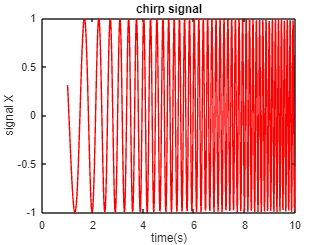

%problem 1 part 1 
alpha=1+mod(163,3);
f1=2+2*alpha;
f2=5+5*alpha;
Fs=100;
t=1:0.01:10-0.01;
t1=10;
chirp_slope=(f2-f1)/t1;
Ft=0.5*chirp_slope*t;
X=sin(2*pi.*Ft.*t);
plot(t,X,'r')
title('chirp signal')
xlabel('time(s)');
ylabel('signal X');

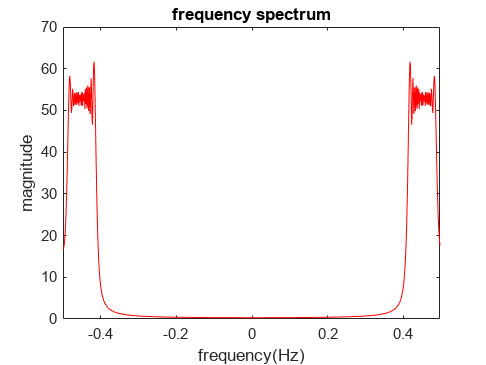


%problem 1 part 2
y=fft(X);
n=length(X);
f=[-n/2:n/2-1]/n;
plot(f,abs(y),'r')
xlabel('frequency(Hz)');
ylabel('magnitude');
title('frequency spectrum');

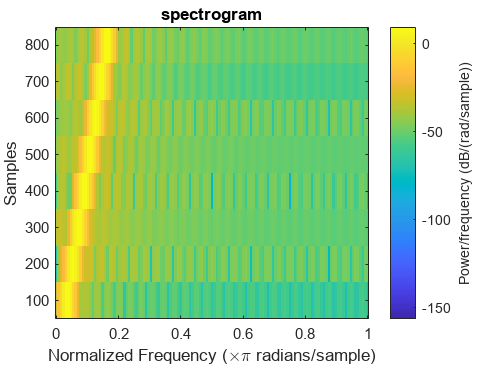


%problem 1 part 3
spectrogram(X)
title('spectrogram');

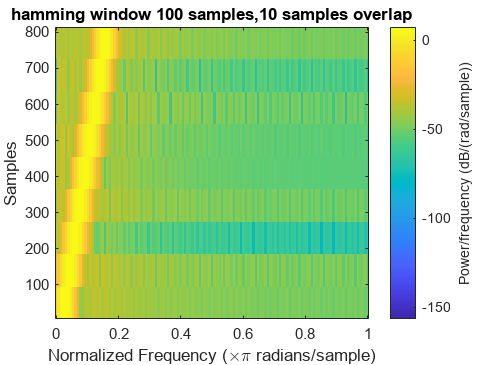

spectrogram(X,100,10)
title('hamming window 100 samples,10 samples overlap');

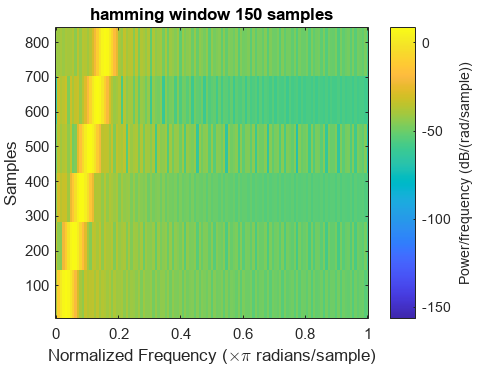

spectrogram(X,150,10)
title('hamming window 150 samples');

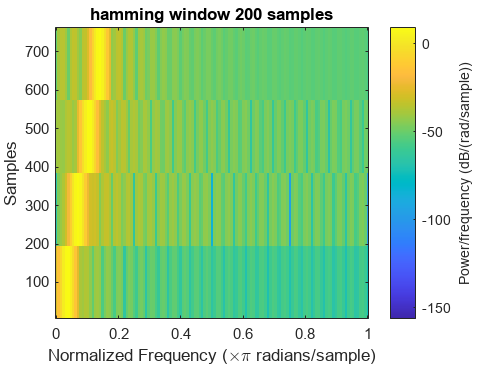

spectrogram(X,200,10)
title('hamming window 200 samples');

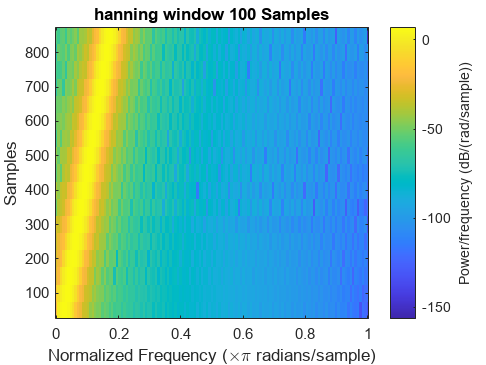

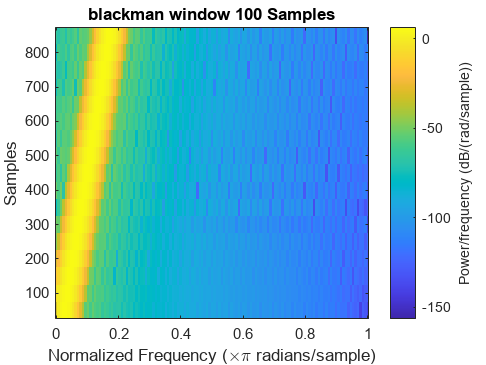

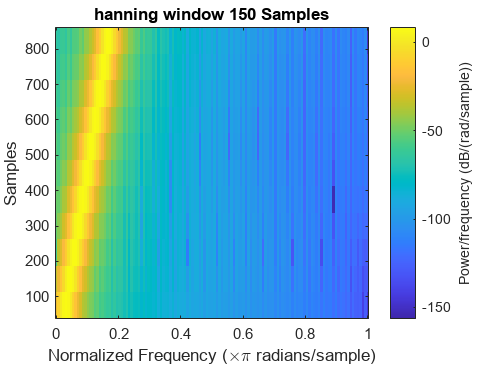

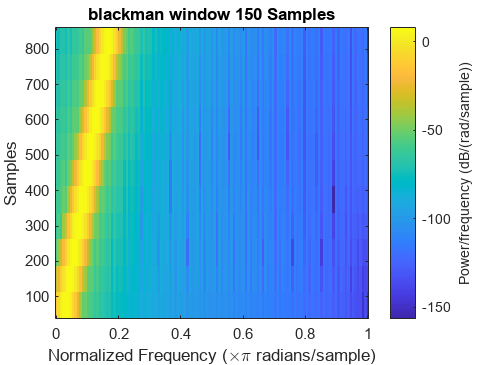

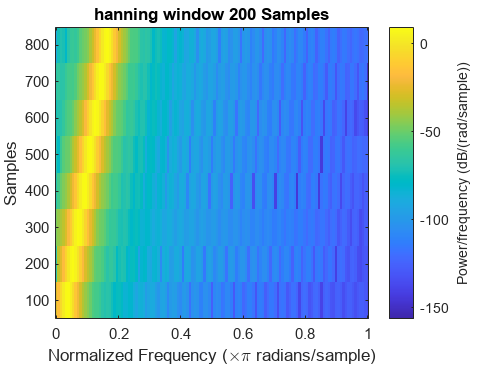

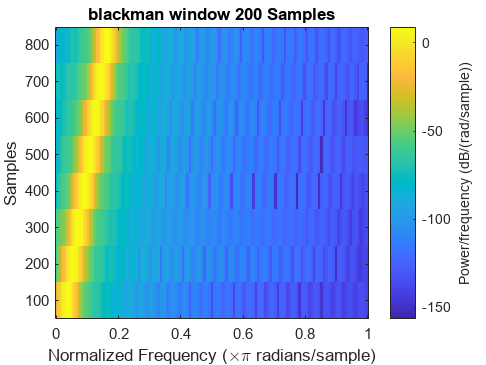


for i=100:50:200
    figure;
    spectrogram(X,hann(i))
    title("hanning window " + i + " Samples")
    figure;
    spectrogram(X,blackman(i))
    title("blackman window " + i + " Samples")
end    

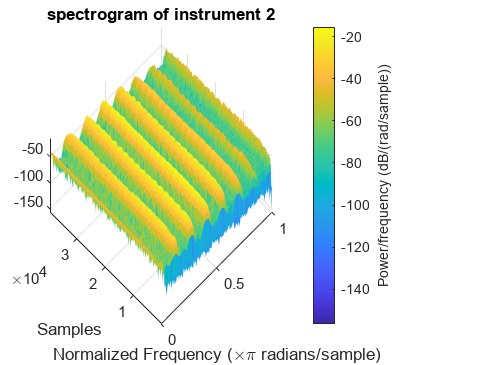

%problem 2
[y1,fs]=audioread('instru2.wav');
spectrogram(y1,100,10),view(-45,65)
title('spectrogram of instrument 2');

f = 0:fs/(length(y1)-1):fs

f = 1.0e+04 *

         0    0.0000    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0008    0.0008    0.0008    0.0008    0.0009    0.0009    0.0009    0.0009    0.0010    0.0010    0.0010    0.0011    0.0011    0.0011    0.0011    0.0012    0.0012    0.0012    0.0013    0.0013    0.0013    0.0013    0.0014


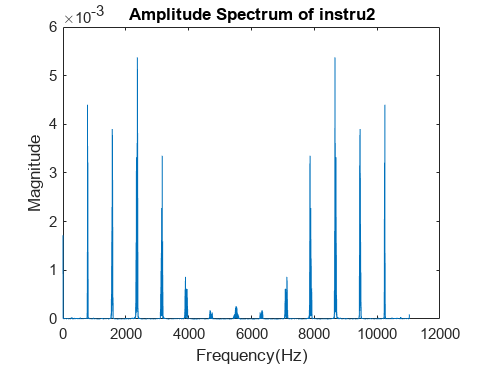

Y = fft(y1);
figure;
plot(f,abs(Y)/(length(y1)))
title("Amplitude Spectrum of instru2")
xlabel("Frequency(Hz)")
ylabel("Magnitude")

[value idx] = max(abs(Y)/(length(y1)));
fund_freq = f(idx)

fund_freq = 2.3692e+03

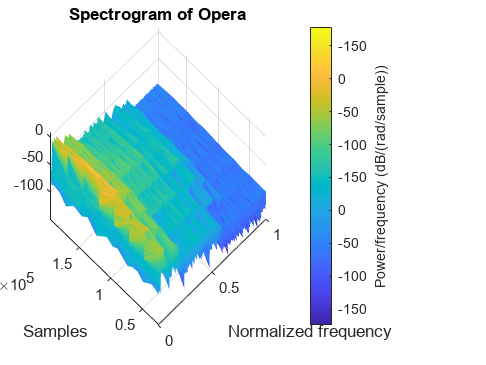


%problem 2 part 2
[y2,fs1] = audioread('opera.wav');
spectrogram(y2),view(-45,60),imagesc()
title("Spectrogram of Opera")
ylabel("Samples")
xlabel("Normalized frequency")

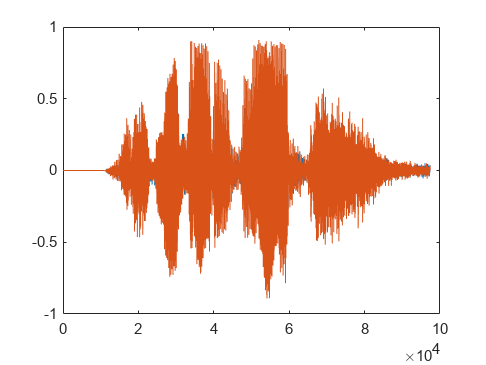


%problem 3
[y3, fs2] = audioread('my name.wav');
plot(y3)

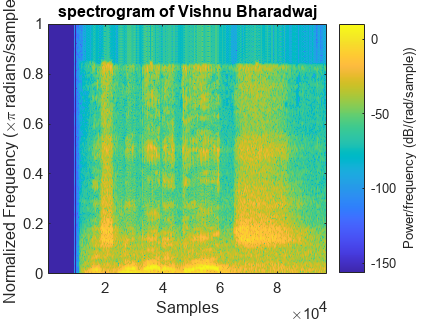

spectrogram(y3(:,2),hamming(300),150,4000,'yaxis')
title("spectrogram of Vishnu Bharadwaj")